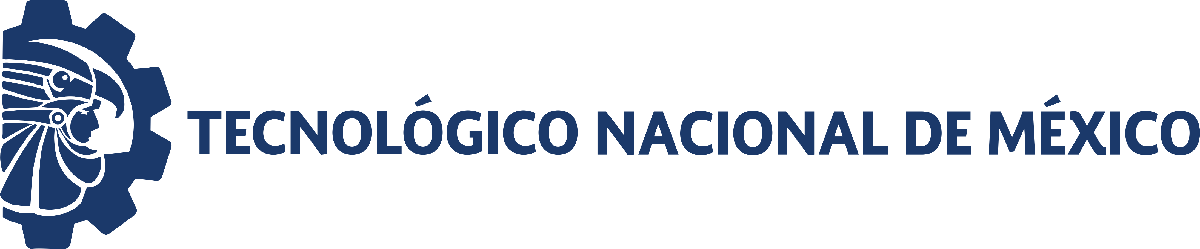                                 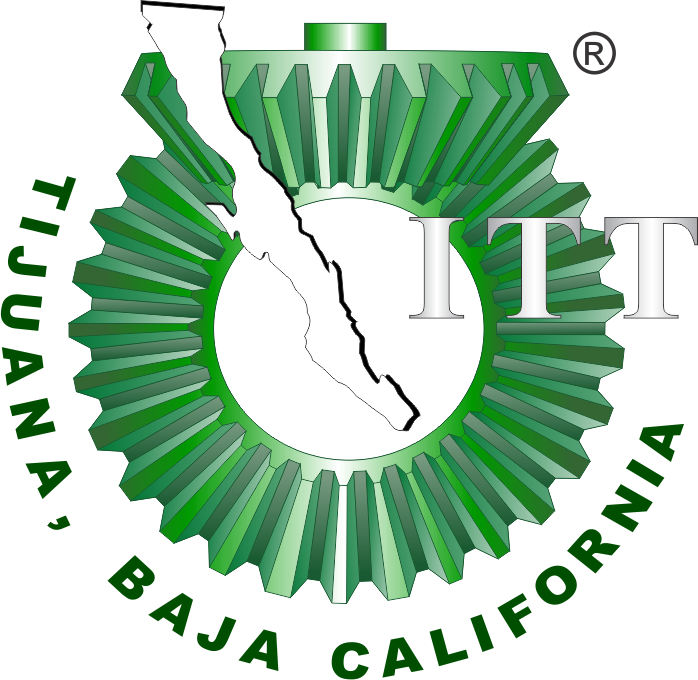

# Práctica 1: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

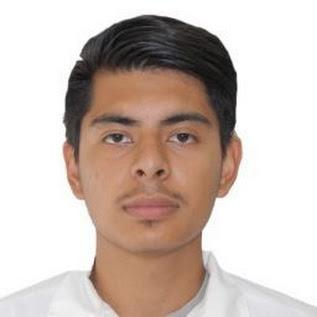

Nombre del alumno: Diego Saul Lopez Islas

Número de control: 22211759

Correo institucional: L22211759@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

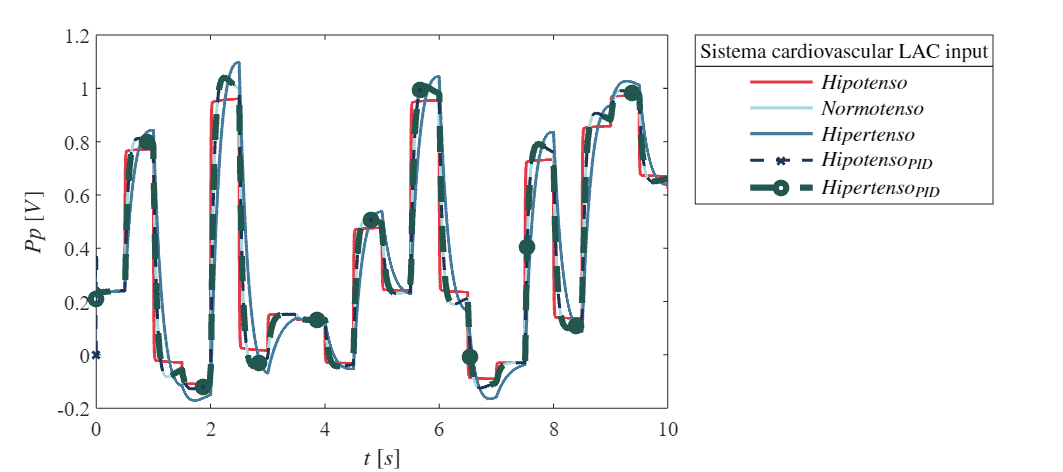

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Simulacion';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
Signal = 'Sistema cardiovascular LAC';
Signal2 = 'Sistema cardiovascular LA';
set_param('Simulacion/Ppa(t)','Minimum','-0.2')
set_param('Simulacion/Ppa(t)','Maximum','1')
set_param('Simulacion/Ppa(t)','Seed','106')
set_param('Simulacion/Ppa(t)','SampleTime','0.5')
X = sim(file,parameters);
writematrix(X.Ppa,'Signal.xlsx')
plotsignals(X.t,X.Pp0,X.Pp1,X.Pp2,X.Pp3,X.Pp4,Signal);

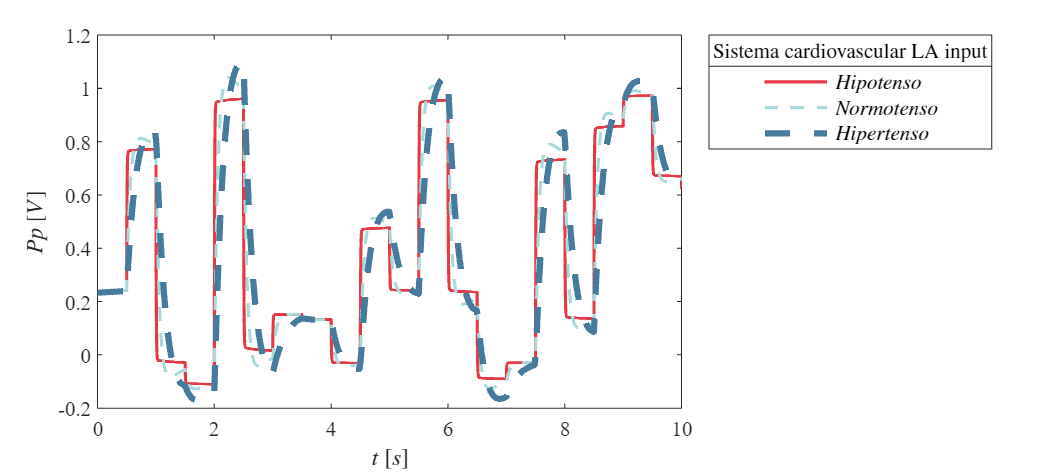

plotsignals2(X.t,X.Pp0,X.Pp1,X.Pp2,Signal2);

**Funcion: Respuesta a las señales**

function plotsignals(t,Pp0,Pp1,Pp2,Pp3,Pp4,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'Fontname','Times New Roman','FontSize',10)
    hold on;grid off;box on;
    mycolor = [0.902,0.224,0.274;
               0.659,0.855,0.863
               0.271,0.482,0.616
               0.114,0.208,0.341
               0.133,0.341,0.310
               0.569,0.392,0.235];
    colororder(mycolor)
    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',t,Pp3,'--x',t,Pp4,'--o',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(5), 'LineWidth',3); 
    L = legend('$Hipotenso$','$Normotenso$','$Hipertenso$','$Hipotenso_{PID}$','$Hipertenso_{PID}$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal,' input'],"FontSize",10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp$ $[V]$','Interpreter','Latex','FontSize',11)

   
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal,'.png'],'ContentType','vector')

 
end
function plotsignals2(t,Pp0,Pp1,Pp2,Signal2)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'Fontname','Times New Roman','FontSize',10)
    hold on;grid off;box on;
    mycolor = [0.902,0.224,0.274;
               0.659,0.855,0.863
               0.271,0.482,0.616];
    colororder(mycolor)
    p = plot(t,Pp0,'-',t,Pp1,'--',t,Pp2,'--',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3), 'LineWidth',3); 
    L = legend('$Hipotenso$','$Normotenso$','$Hipertenso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,[Signal2,' input'],"FontSize",10);

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp$ $[V]$','Interpreter','Latex','FontSize',11)

   
    exportgraphics(gcf,[Signal2,'.pdf'],'ContentType','vector')
    exportgraphics(gcf,[Signal2,'.png'],'ContentType','vector')
end
